clear all; close all

%load(['controller_test_frf_uitgebreide_controller_deze_keer_echt_de_goede.mat'])
load("experiment_open_loop_15_04.mat")

%{
u = measurement(:,2)
d = measurement(:,1)
%}

%data analysis
fs = 4000 %[Hz]

fs = 4000

stepsize = 1/fs %[s]

stepsize = 2.5000e-04

max_freq = log10(fs/2) 

max_freq = 3.3010

%t_end = N_samples/fs

angle(exp(-100*stepsize*i))* 180/pi %phase los at 100 Hz due to discretization

ans = -1.4324


%removing uselss data 
N_trash = 1000; 
u = u(N_trash:end)

u =    -2.2499
   -2.1367
   -1.7139
   -2.1342
   -2.3809
   -2.9083
   -2.6674
   -2.4458
   -2.6005
   -2.5423


d = d(N_trash:end)

d =     0.0463
    0.1735
    0.6105
    0.2044
   -0.0242
   -0.5344
   -0.2793
   -0.0424
   -0.1820
   -0.1083


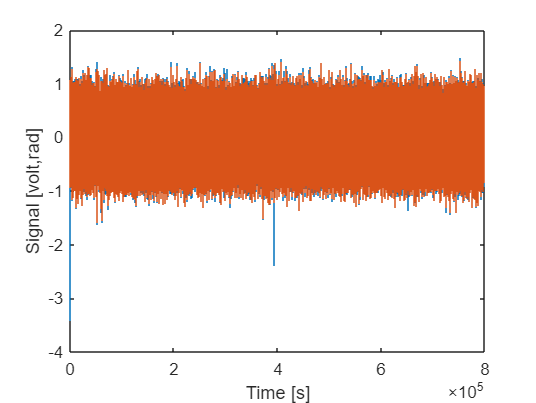


% Plot the measurement
figure(); clf();
stairs(u); hold on; stairs(d);
xlabel('Time [s]'); ylabel('Signal [volt,rad]');
hold off

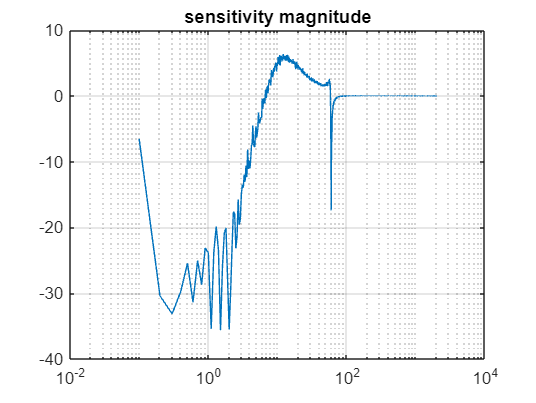


%window settings
min_freq = 0.1; %[Hz/s] lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds

nfft = round(windowsize/stepsize); %window size in data points 
n_overlap = round(nfft/5);

%Tf estimate
[Sud, F] = tfestimate(d,u,hann(nfft),n_overlap,nfft,fs); %cross spectral power density
Sdd = pwelch(d,hann(nfft)); %spectral power disturbance
Suu = pwelch(u,hann(nfft)); %spectral power input
%S =  Sud./Sdd; %sensitivity function
S = Sud;

figure()
semilogx(F,mag2db(abs(S)))
title("sensitivity magnitude")
grid on; hold off

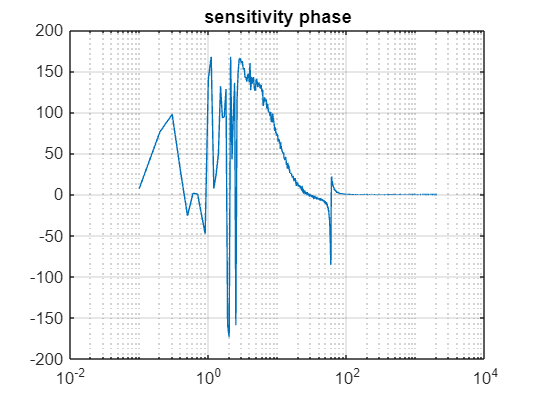


figure()
semilogx(F,angle(S)/pi*180)
title('sensitivity phase')
grid on; hold off

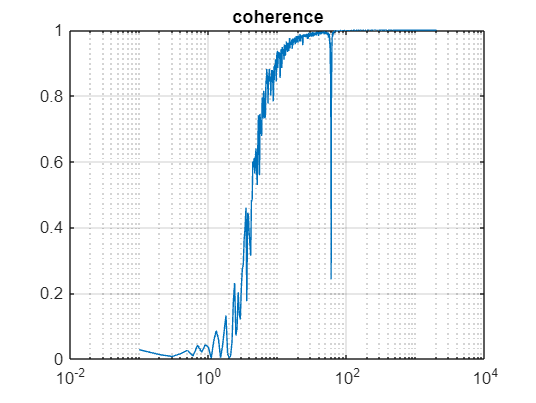


%plotting coherence 
figure()
[coherence_ry, f] = mscohere(d,u,hann(nfft),n_overlap,nfft,fs);
semilogx(f,coherence_ry)
title('coherence')
grid on; hold off

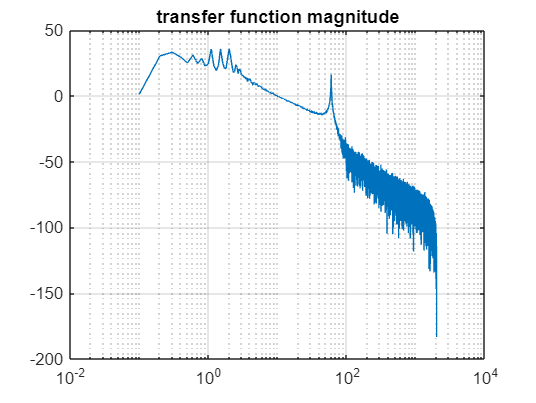

   
%plotting open loop transfer function
L = 1./S - 1;
figure()
semilogx(F,mag2db(abs(L)))
title('transfer function magnitude')
grid on; hold off

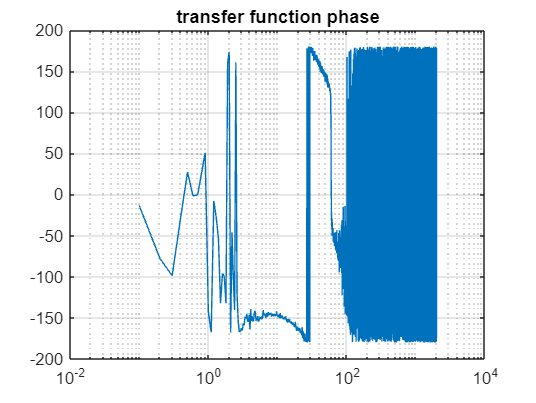


figure()
semilogx(F,angle(L)/pi*180)
title('transfer function phase')
grid on; hold off

n_trash = 30;
L_short = L(n_trash:end);
F_short = F(n_trash:end);
sys = frd(L_short,F_short)

sys =
 
    Frequency(rad/s)            Response       
    ----------------            --------       
           2.9000       -9.456e+00 - 2.186e+00i
           3.0000       -6.299e+00 - 1.962e+00i
           3.1000       -5.505e+00 - 1.424e+00i
           3.2000       -5.411e+00 - 2.331e+00i
           3.3000       -4.554e+00 - 1.746e+00i
           3.4000       -4.539e+00 - 2.764e+00i
           3.5000       -3.702e+00 - 2.056e+00i
           3.6000       -4.056e+00 - 2.829e+00i
           3.7000       -3.100e+00 - 1.467e+00i
           3.8000       -4.020e+00 - 1.952e+00i
           3.9000       -3.252e+00 - 2.139e+00i
           4.0000       -4.332e+00 - 1.228e+00i
           4.1000       -2.790e+00 - 2.393e+00i
           4.2000       -2.922e+00 - 1.440e+00i
           4.3000       -2.627e+00 - 1.635e+00i
           4.4000       -2.276e+00 - 1.090e+00i
           4.5000       -2.848e+00 - 1.398e+00i
           4.6000       -2.605e+00 - 1.804e+00i
           4.7000       -2.466e+

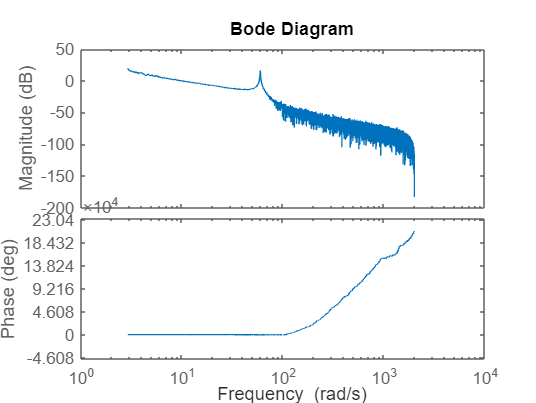

bode(sys)

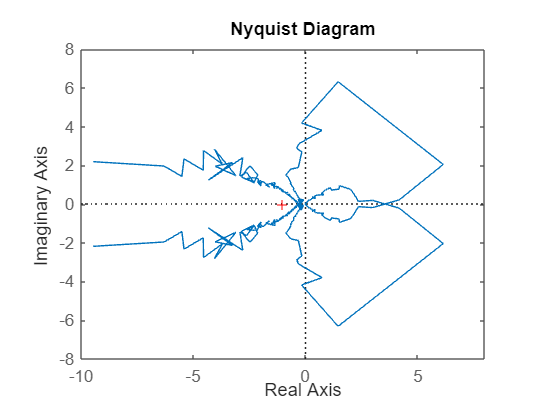

nyquist(sys)